# Feature space

## Overview

The overall aim in this lab is to build a 2D abstraction visualisation function that will let you generate abstractions like the ones we saw in the lecture, for any classifier trained on two predictive features (including your own classifier re-implementations). If you can see what is required based on the lecture, then great, please jump in. Complete the `visualise_abstraction()` function stub, and check your finished code produces the same results shown in the tasks below.

If you're not so sure how to proceed, then the tasks below help you through the process of writing the `visualise_abstraction()` function step by step.

## Refresher: the machine learning recipe

Below is another reminder of the machine learning recipe, applied to a classification problem based on the sepal.csv dataset. The only difference this time is that we use a value of k=3 for our k-NN classifier. Take a moment to read over the code once again; each of the steps should now be very familiar. If you're unsure of anything then consider repeating the commenting exercise, looking back at previous scripts/lectures for help, and/or asking for help:

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

data = readcell('sepal.csv');

data(1:1:10, 1:1:end)

ans = 10×3 cell array
    {'sepal_length'}    {'sepal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {'setosa' }



obs = data(2:end,:);

obs_shuffled = obs(randperm(size(obs,1)), :);

nTest = round(0.4 * size(obs_shuffled,1))

nTest = 60


obs_test = obs_shuffled(1:1:nTest, :);
obs_train = obs_shuffled(nTest+1:1:end, :);

label_index = 3;

test_labels = categorical(obs_test(:, label_index));
test_examples = cell2mat(obs_test(:, 1:end~=label_index));

size(test_examples)

ans =     60     2


size(test_labels)

ans =     60     1



train_labels = categorical(obs_train(:, label_index));
train_examples = cell2mat(obs_train(:, 1:end~=label_index));

size(train_examples)

ans =     90     2


size(train_labels)

ans =     90     1



m_knn = fitcknn(train_examples, train_labels, 'NumNeighbors', 3)

m_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
                 Distance: 'euclidean'
             NumNeighbors: 3


  Properties, Methods



predictions = m_knn.predict(test_examples);

p_knn = sum(predictions == test_labels) / length(test_labels)

p_knn = 0.7833

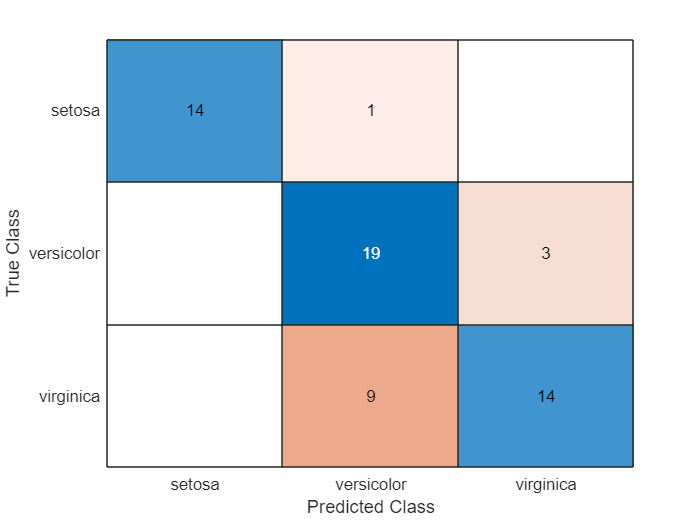


figure; confusionchart(test_labels, predictions)

## Visualising the feature space

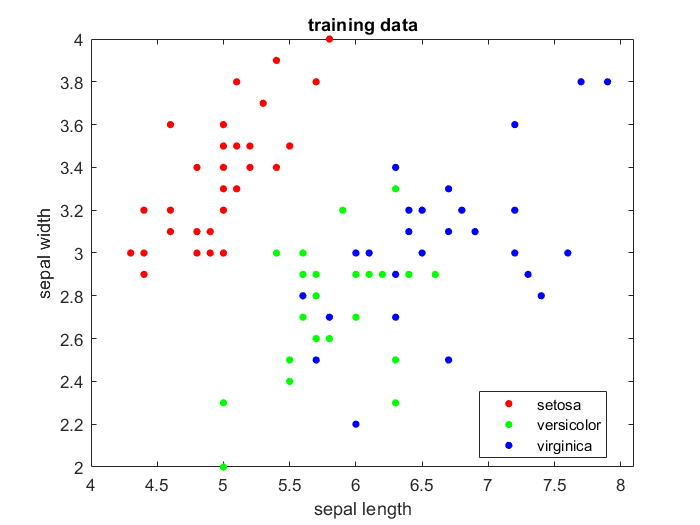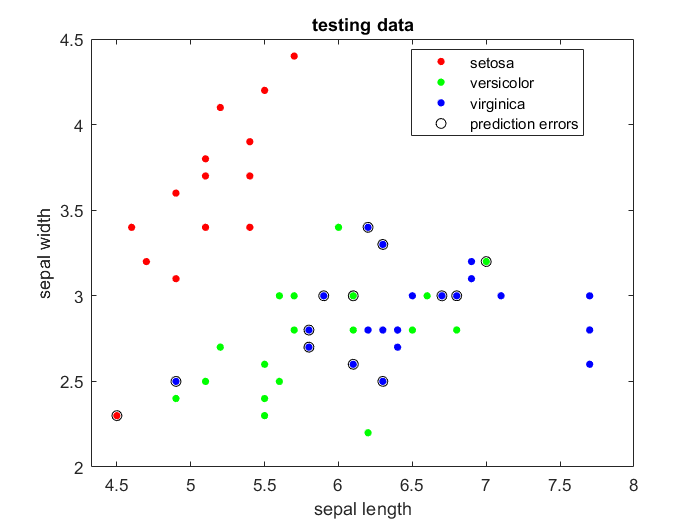

Now use `gscatter()` to visualise the training examples as single points in a 2D feature space, colour coded by their associated class labels (see the previous lab for help using `gscatter()` if you need it):

(**Sanity check**: you should be able to produce something very similar to the left-hand image above.)

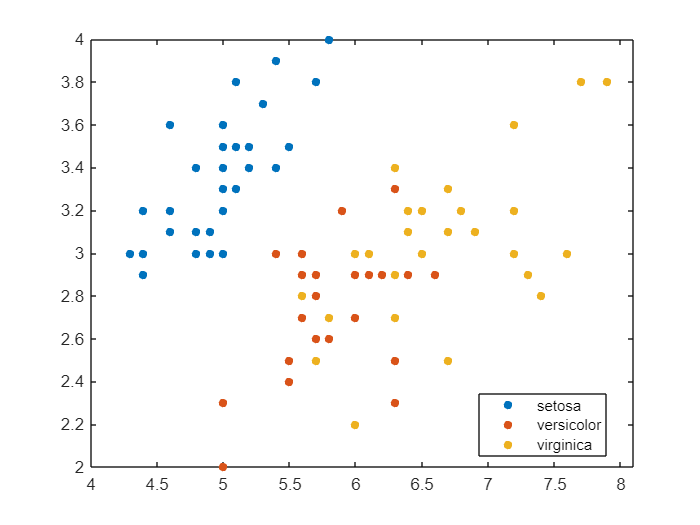

figure; % open a new figure window, ready for plotting

% add your code on the lines below:
gscatter(train_examples(:,1),train_examples(:,2),train_labels)

Now produce another similar feature space visualisation for the testing data and use the `scatter()` function to highlight those testing examples that are misclassified by the model by surrounding them with black circles (see the previous lab sheet for help using `scatter()` if you need it):

(**Hint**: you can write a simple, one-line logical test to find the indices of the predicted labels (in `predictions`) which didn't agree with the testing labels (in `test_labels`); see the accuracy calculation in the previous section for inspiration if needed)

(**Sanity check**: you should be able to produce something very similar to the right-hand image above.)

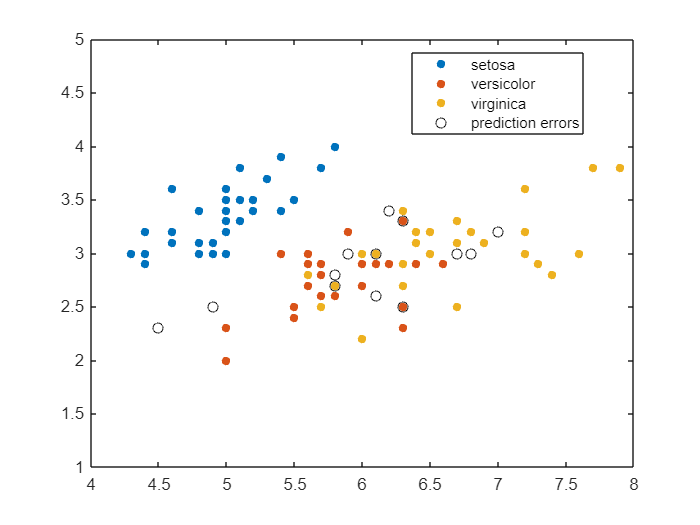

figure; % open a new figure window, ready for plotting

% add your code on the lines below:
gscatter(train_examples(:,1),train_examples(:,2),train_labels)
ylim([1 5]);
xlim([4 8]);

hold("on");
n=0;



for i = 1:1:size(test_examples)
    if predictions(i,1) ~= test_labels(i,1)
        n = n + 1;
        err(n,1) = test_examples(i,1);
        err(n,2) = test_examples(i,2);
    end
end
scatter(err(:,1), err(:,2), 'ok', 'DisplayName', 'prediction errors');

## Visualising the abstraction - a manual approach

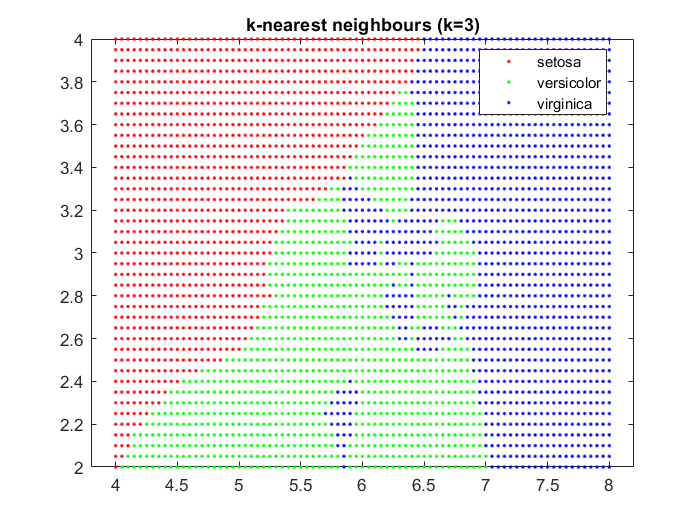

During its fitting phase, a classifier goes from the specific training examples and class labels we supply, to a more general concept of "what is class A", "what is class B", etc. This process is referred to as the classifier *abstracting* the data, or creating *an abstraction* (see also the lecture slides). The abstraction allows the classifier to make a prediction about which class a new testing example belongs to, even if it hasn't seen the example before.

In terms of our feature space representation, the classifier can use its abstraction to make predictions for new testing examples no matter where in the feature space those examples lie.

By covering a portion of feature space with a regular "grid" of testing examples and then using a classifier to predict their associated class labels, we can build up a picture of the abstraction the classifier has learned (see the image above, for example).

The aim here is to use some quick, hard-coded assumptions and a built-in Matlab helper function to build up a 2D abstraction visualisation using this grid-based approach. (In the later tasks, we'll then work on removing the assumptions and the dependency on the built-in helper function.)

You can use the built-in Matlab helper function `meshgrid(x, y)` to generate 2D coordinates for a grid of points ranging over the x-values in the array `x` and the y-values in the array `y`. Have a look at the output from the simple example below to get the idea:

[Xs , Ys] = meshgrid(1:0.5:2, 2:0.5:3)

Xs =     1.0000    1.5000    2.0000
    1.0000    1.5000    2.0000
    1.0000    1.5000    2.0000


Ys =     2.0000    2.0000    2.0000
    2.5000    2.5000    2.5000
    3.0000    3.0000    3.0000


The results are returned as 2D arrays with the same size as the grid. I.e., you can get the coordinates for the grid point in the third row down from the top and the second column along from the left, as follows:

Xs(3,2)

ans = 1.5000

Ys(3,2)

ans = 3

Or it's easy to reorganise the coordinates into a single column of x-values and a single column of y-values as follows:

grid_examples = [Xs(1:1:end)' Ys(1:1:end)']

grid_examples =     1.0000    2.0000
    1.0000    2.5000
    1.0000    3.0000
    1.5000    2.0000
    1.5000    2.5000
    1.5000    3.0000
    2.0000    2.0000
    2.0000    2.5000
    2.0000    3.0000


Which enables you to plot them easily, for example, using the `scatter()` function:

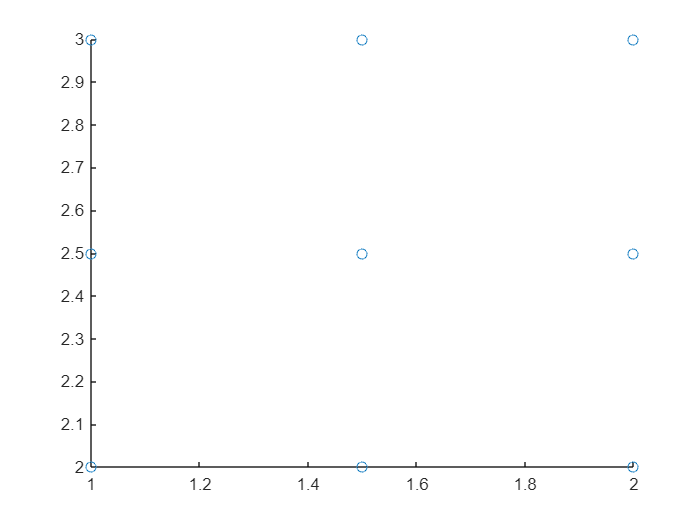

figure; % open a new figure window, ready for plotting
scatter(grid_examples(:,1), grid_examples(:,2))

Notice also that the resulting `grid_examples` array has the same shape as an array of testing examples with two predictive feature values per row. We could therefore pass it to a classifier like the one we trained earlier, in order to generate predicted labels for each point in the grid (by calling the classifier's `predict()` method). We could then use the resulting predictions to make a call to `gscatter()` and generate a colour-coded visualisation of the grid, and therefore the classifier's abstraction...

Have a go at using `meshgrid()` to generate a grid of testing examples that covers the region of feature space you plotted in the previous task. Then pass them to the k-NN classifier we trained in the first section in order to generate predictions, and use `gscatter()` to plot your new testing examples, colour-coded by their associated predicted labels. You should be able to produce a visualisation of the classifier's abstraction very similar to the one shown in the image above:

(**Hints**: look back at the training data feature space plot in the previous task as a guide; we recommend your x-values cover approximately the same range as the axes on that graph (between 4-8 for the x-values and between 2-4 for the y-values) and that you keep the spacing between points in your grid relatively small at, say, 0.05)

(**Sanity check**: you should be able to produce something very similar to the image above.)

figure; % open a new figure window, ready for plotting

% add your code on the lines below:
[Xs ,Ys] = meshgrid(4:0.05:8, 2:0.05:4)

Xs =     4.0000    4.0500    4.1000    4.1500    4.2000    4.2500    4.3000    4.3500    4.4000    4.4500    4.5000    4.5500    4.6000    4.6500    4.7000    4.7500    4.8000    4.8500    4.9000    4.9500    5.0000    5.0500    5.1000    5.1500    5.2000    5.2500    5.3000    5.3500    5.4000    5.4500    5.5000    5.5500    5.6000    5.6500    5.7000    5.7500    5.8000    5.8500    5.9000    5.9500    6.0000    6.0500    6.1000    6.1500    6.2000    6.2500    6.3000    6.3500    6.4000    6.4500
    4.0000    4.0500    4.1000    4.1500    4.2000    4.2500    4.3000    4.3500    4.4000    4.4500    4.5000    4.5500    4.6000    4.6500    4.7000    4.7500    4.8000    4.8500    4.9000    4.9500    5.0000    5.0500    5.1000    5.1500    5.2000    5.2500    5.3000    5.3500    5.4000    5.4500    5.5000    5.5500    5.6000    5.6500    5.7000    5.7500    5.8000    5.8500    5.9000    5.9500    6.0000    6.0500    6.1000    6.1500    6.2000    6.2500    6.3000    6.3500    6.4000    

Ys =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    2.0500    

grid_examples = [Xs(1:1:end)' Ys(1:1:end)']

grid_examples =     4.0000    2.0000
    4.0000    2.0500
    4.0000    2.1000
    4.0000    2.1500
    4.0000    2.2000
    4.0000    2.2500
    4.0000    2.3000
    4.0000    2.3500
    4.0000    2.4000
    4.0000    2.4500



dots = predict(m_knn,grid_examples)

dots = 3321×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 


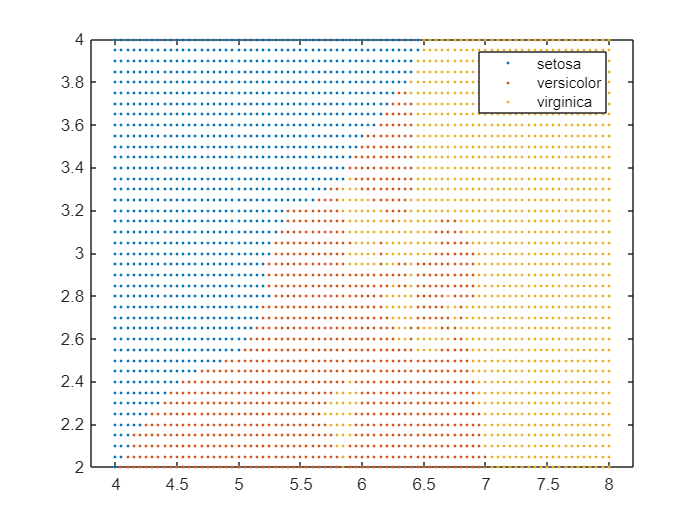



gscatter(grid_examples(:,1),grid_examples(:,2),dots)

## Visualising the abstraction - an automatic approach

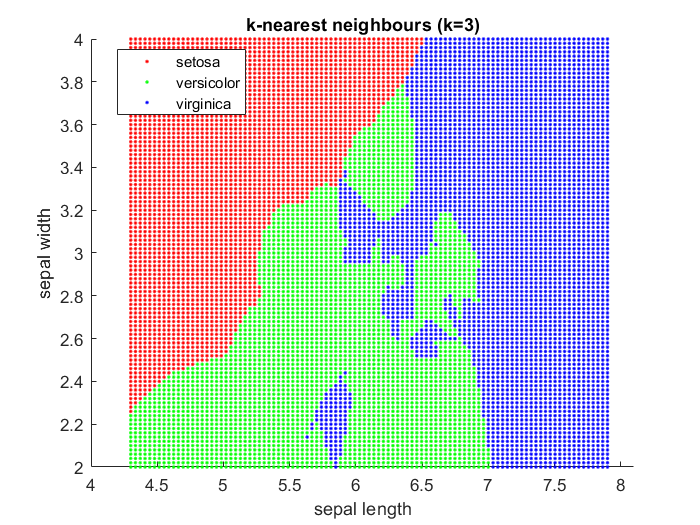

Have a think about how you can automate your call to `meshgrid()`, based on the data stored inside a model object from a class like `ClassificationKNN`. Remember that you have access to the training examples in the X property, and that you can use functions like `min()` and `max()` to work out the minimum/maximum values for each feature, and therefore an appropriate region of feature space to focus your visualisation on. Rather than setting the grid spacing to a constant value (which might not be appropriate for smaller/larger feature values), can you set your visualisation to use a horizontal grid spacing equal to 1/100th of the grid's overall width, and a vertical grid spacing equal to 1/100th of the grid's overall height.

Starting with a copy/paste of your code from the previous task, try to produce another visualisation of the same classifier's abstraction, while minimising the number of hard-coded values in your code:

(**Sanity check**: you should be able to produce a similar visualisation to the one shown above (axes labels and title are optional), with the only hard-coded value being 100 (controlling the horizontal/vertical grid spacing))

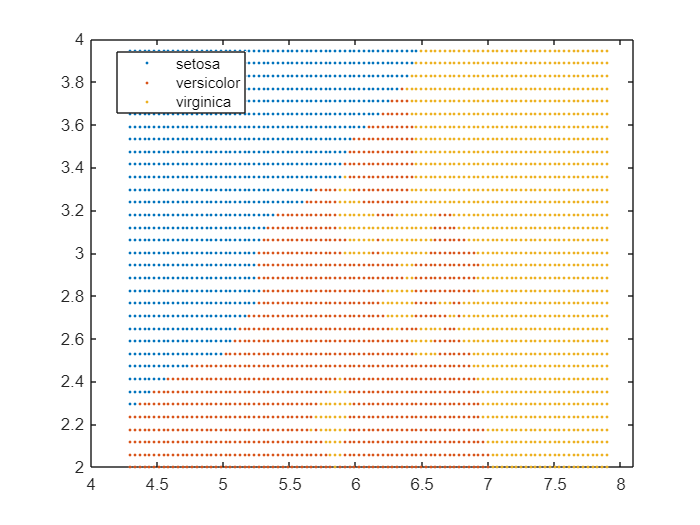

figure; % open a new figure window, ready for plotting

% add your code on the lines below:
[Xs Ys] = meshgrid(min(m_knn.X(:,1)):(max(m_knn.X(:,1))-min(m_knn.X(:,1)))/100:max(m_knn.X(:,1)), min(m_knn.X(:,2)):(max(m_knn.X(:,1))-min(m_knn.X(:,2)))/100:max(m_knn.X(:,2)));
grid_examples = [Xs(1:1:end)' Ys(1:1:end)'];

dots = predict(m_knn,grid_examples);


gscatter(grid_examples(:,1),grid_examples(:,2),dots)

## Implementing a reusable visualisation function part I

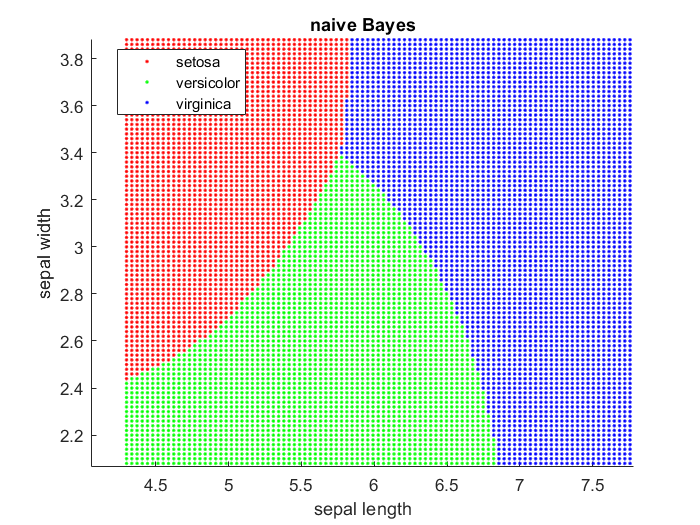

Now reuse your code from the previous task to extend the `visualise_abstraction()` function stub, which takes a model object as its only argument, so that it can generate an abstraction visualisation for *any* classifier trained on examples containing two predictive feature values.

Check you can uncomment the code below in order to generate abstraction visualisations for the k-NN classifier we trained in the first section, and for a new naive Bayes classifier, trained on the same training data:

(**Sanity check**: the visualisations should match with the images shown at the start of this task, and the last task)

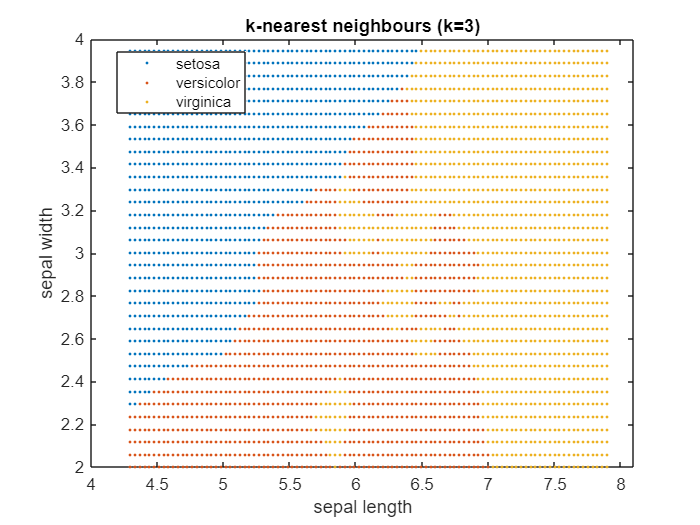

visualise_abstraction(m_knn);
xlabel('sepal length');
ylabel('sepal width');
title('k-nearest neighbours (k=3)');

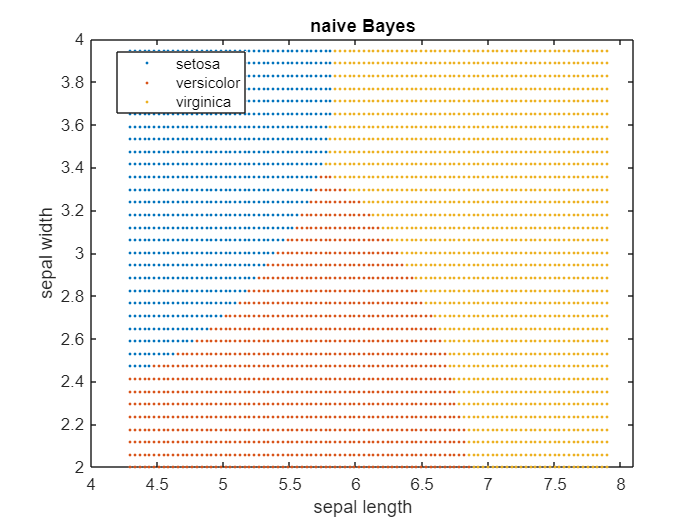


m_nb = fitcnb(train_examples, train_labels);
visualise_abstraction(m_nb);
xlabel('sepal length');
ylabel('sepal width');
title('naive Bayes');

Because we named our object properties consistently, your completed `visualise_abstraction()` function should work with either a `ClassificationNaiveBayes` object *or* a `my_ClassificationNaiveBayes` object. And if you implemented the `my_fitcknn()` function and `my_ClassificationKNN` object in the previous lab then the same is true there as well.

Check you can uncomment the code below in order to generate abstraction visualisations for models made using the re-implementations (the second visualisation will only be possible if you have completed the previous lab tasks):

(**Hints**: Now you're processing quite a lot of testing data you'll notice the benefits of switching off Verbose and using memory pre-allocation in the re-implementations; if run-times are still too slow, or you're doing lots of testing, you can also increase the grid spacing used by your `visualise_abstraction()` function to speed things up)

(**Sanity check**: You should recover visualisations identical to the ones you got above.)

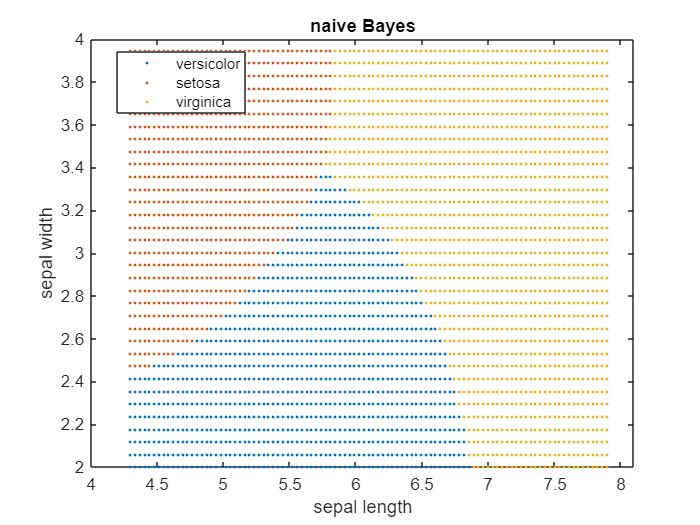

mym_nb = my_fitcnb(train_examples, train_labels);
visualise_abstraction(mym_nb);
xlabel('sepal length');
ylabel('sepal width');
title('naive Bayes');


mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 3);
visualise_abstraction(mym_knn);
xlabel('sepal length');
ylabel('sepal width');
title('k-nearest neighbours (k=3)');

## Implementing a reusable visualisation function part II

Can you now remove your code's dependency on the built-in `meshgrid()` function? 

Rather than trying to mimic the `meshgrid()` function's output exactly, we would suggest writing some code to produce an array in a convenient shape (i.e., containing one example per row and therefore avoiding you having to do the reshaping needed after the original calls to `meshgrid()`).

(**Hint**: we recommend writing a nested for loop to generate your grid of testing examples)

(**Sanity check**: your code for the previous tasks should still generate exactly the same visualisations, regardless of whether your `visualise_abstraction()` function is calling on `meshgrid()` or not)

## Varying the hyperparameter k

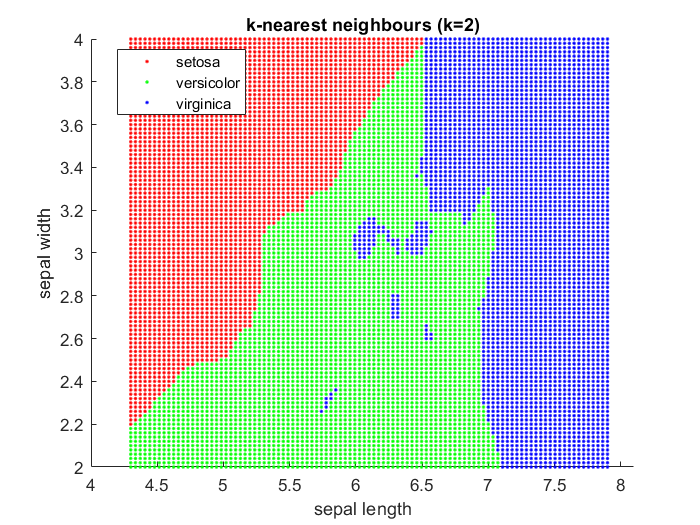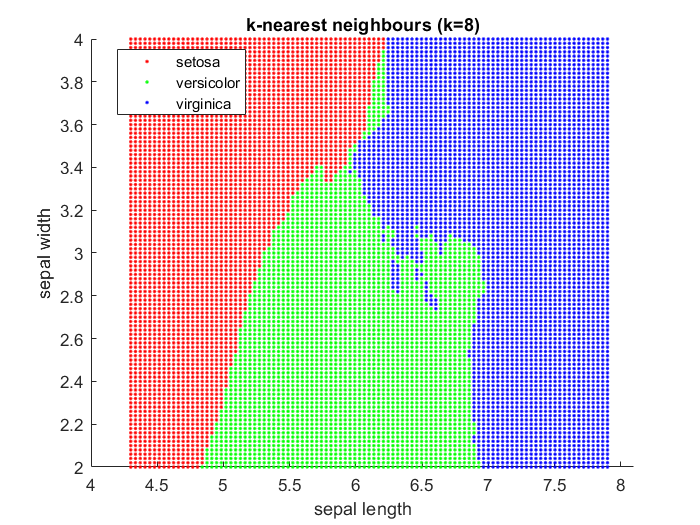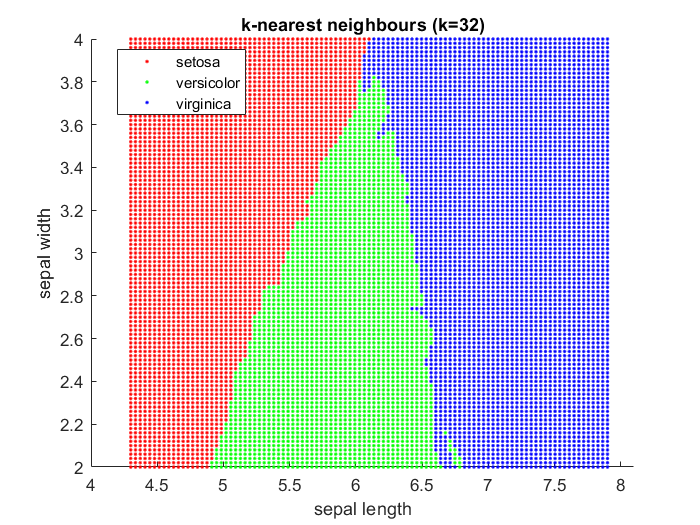

Working with the same sepal.csv dataset and using your `visualise_abstraction()` function, try generating visualisations of the abstractions produced when using some different values of k (e.g., k=2, 8, 32, etc.). You can use the built-in (`fitcknn()`) implementation for speed - this is just an opportunity to have a look at some different abstractions...

(**Sanity check**: the abstractions for k=2, k=8 and k=32 are shown in the images above, for comparison)

% add your code on the lines below


